# Orientation Kinematics

clear; clc; close all;

In this document, we will think about kinematics of orientations in 3D space. Additionally, we will adopt reference frame conventions similar to those used in Pinocchio, for smoother transitions to implementing on hardware. The reference frames considered will be:

- O: World Frame

- B: Local Frame (Body Frame)

- A: World Aligned Local Frame

The code below considers a rigid body, located at position (1,1,1), with roll and pitch angles of 45deg. The given frames are visualized:

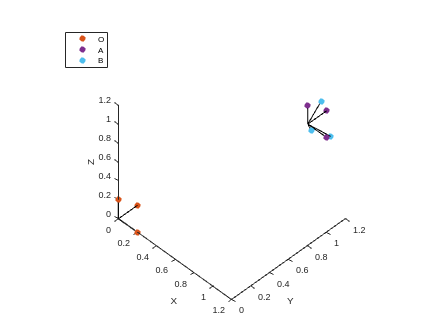

p = [1 1 1]';
roll_deg = 45;
pitch_deg = 45;

fh1 = figure();
plot_frame(fh1, [0,0,0]', eye(3), 'rot', 'O')
plot_frame(fh1, p, eye(3), 'rot', 'A')
plot_frame(fh1, p, eul2rotm(deg2rad([roll_deg, pitch_deg, 0]), 'XYZ'), 'rot', 'B')

## Representing Orientation and Pose

There are several ways of representing orientations and poses of rigid bodies in 3D space. The translational component is straightforward to represent, composed of a vector $p \in \mathbb{R}^3$. The rotational component is accompanied by a choice; several representations (such as euler angles, or any 3-number parameterization) have singularities, while others (requiring 4 or more numbers) are singularity free. Singular representations work if orientations do not deviate far from an operating point, but singularity free represenations are much cleaner. Therefore, we will primarily consider singularity free representations, namely the rotation matrix, $R \in SO(3)$, and the quaterion $q \in S^3$. 

### Rotation Matrices

A rotation matrix encodes the orientation of a rigid body by locating the axes of the body frame ($B$) in the world frame ($O$). In general, take the matrix $^AR_B \in SO(3)$ to be a rotation matrix expressing the orientation of frame $B$ in reference to the frame $A$.  

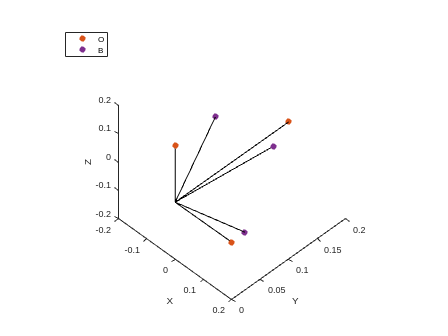

x = [1 1 1]'; x = x / norm(x);
y = [0.5 0.5 -1]'; y = y / norm(y);
z = cross(x, y);

R_ob = [x y z];
fh2 = figure();
plot_frame(fh2, [0,0,0]', eye(3), 'rot', 'O')
plot_frame(fh2, [0,0,0]', R_ob, 'rot', 'B')

### Quaternions

Quaterions represent the orientation of a rigid body by a 4-tuple of numbers, which have unit magnitude.  The set of quaternions double-cover the space of rotations, as a quaternion and its negative represent the same orientation.

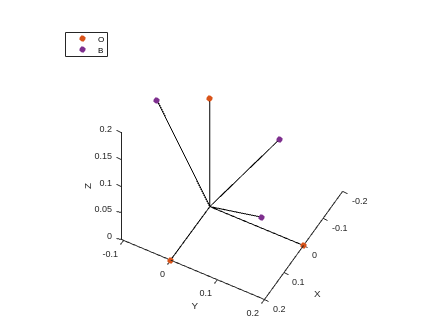

q = rand(1, 4); q = q / norm(q);
fh3 = figure();
plot_frame(fh3, [0,0,0]', eye(3), 'rot', 'O')
plot_frame(fh3, [0,0,0]', q, 'quat', 'B')